# P06: Sistemas de inferencia difusos (FIS)

## Integrantes

- **Arellano Paz Ángel Ulises **

- **García Arteaga Alejandro **

- **Pérez Aboytes David **

- **Quijano Gutiérrez Luis Humberto **

- **Soto García Pablo Yael **

## Introducción

La diferencia en los sistemas de inferencia (sugeno, mamdani y Tsukamoto), radica en como se representan las variables de salida. El modelo propuesto por Tsukamoto, se diferencia por presentar el consecuente de cada una de las reglas difusas por medio de un conjunto borroso, con su respectiva función de pertenencia monótona.

La salida de cada regla es un valor numérico dado por el grado de pertenencia a la regla evaluada. El resultado final se obtiene por la media ponderada de las salidas parciales. Este tipo de modelo economiza tiempo en el proceso de la defusificación, pero no son tan claros como el sugeno y mamdani.

En resumen, la función consecuente es un conjunto difuso con una función: If A is U and B is V then C=Z, la salida de cada regla difusa es un valor exacto y este método no necesita defusificacion, en lugar de eso se utiliza el promedio ponderado.

## Problema 1

Vamos a recrear el problema de la propina donde se puede observar una implementacion mediante la inferencia tipo Mandani, esto a partir de la herramienta grafica de Matlab para generar la inferencia tipo Mandani.

primero nos dirigimos a la pestaña de apps y elegimos la opcion de Fuzzy Logic Designer.

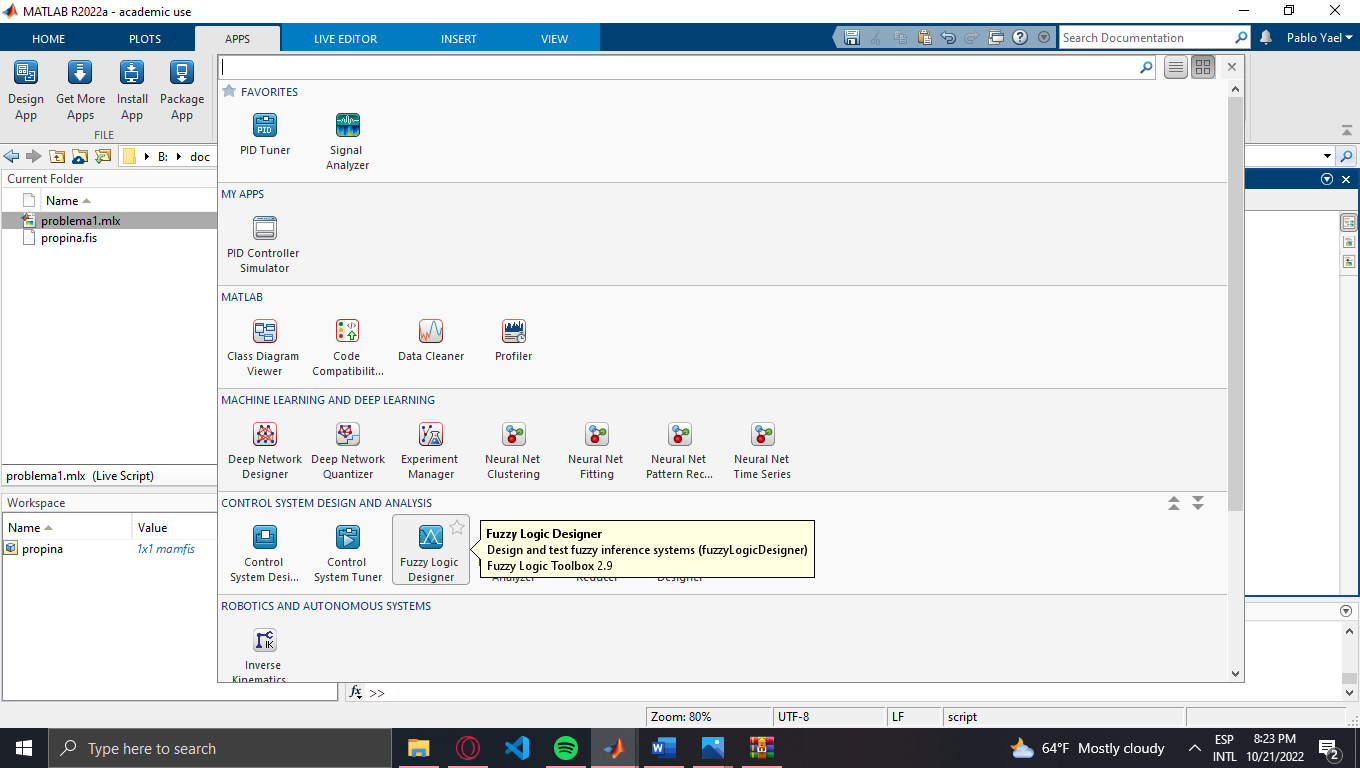

una vez seleccionado pordemos observar una pestaña como la siguiente:

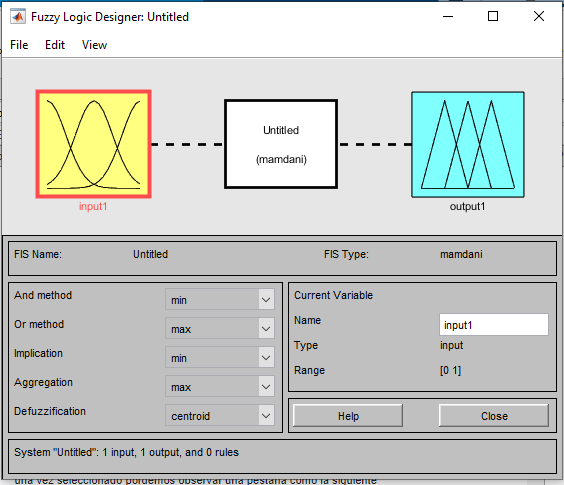

para agregar la segunda entrada, nos dirigimos al apartado de edit-Add variable-Input

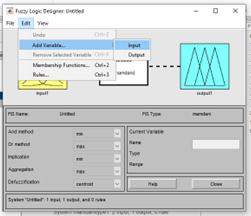

esto generara una segunda entrada.

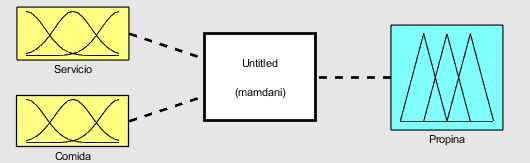

para cambiar los nombres de las variables vamos a la seccion de Current Variable y editamos el nombre.

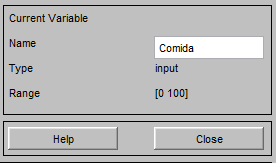

damos doble click en la variable que queramos editar, y editamos las variables que queremos editar, en este caso el rango

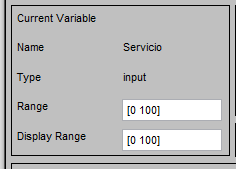

y esto lo realizamos con todas las variables

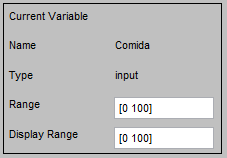

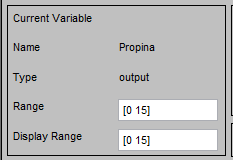

ya que tenemos los rangos definidos asignaremos valores linguisticos asignados a cada una de las variables, empezamos dirigiendonos al apartado de edit-add Mfs

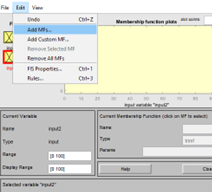

ahi asignamos el total de valores y elegimos el tipo de valor

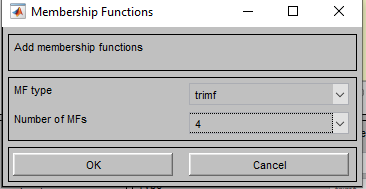

asignamos el nombre a cada uno de los valores linguisticos en el bloque de Current Membership Function, en su apartado name

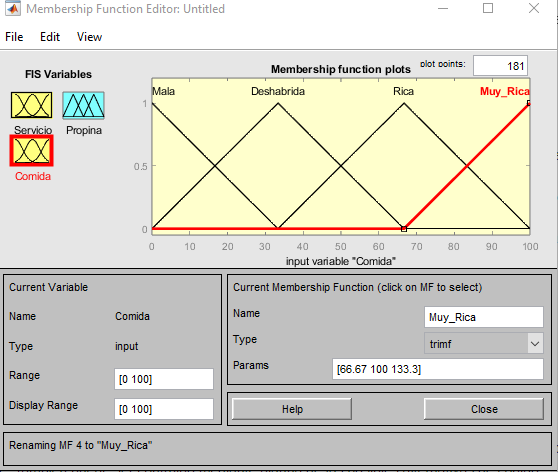

realizamos el mismo procedimiento para el servicio y la propina

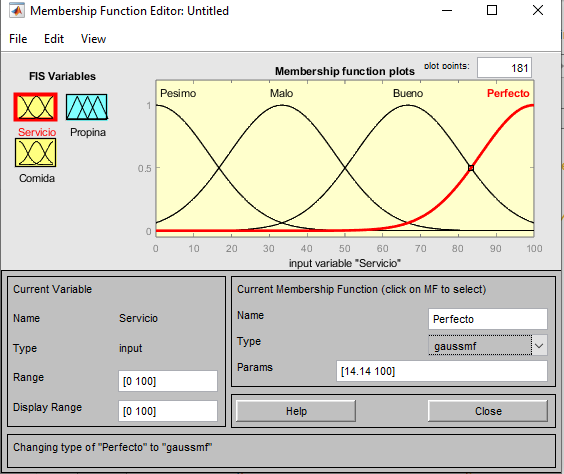

editando las funciones de membrecía para cada variable se observa 

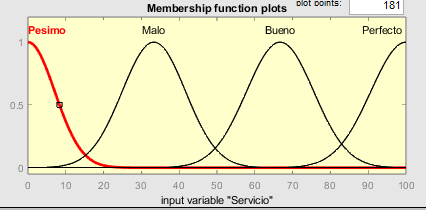

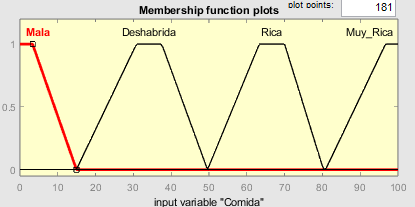

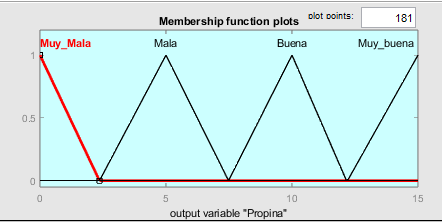

Ya tenemos asignadas y configuradas cada una de las variables en el sistema, ahora solo queda asignar las reglas en la inferencia tipo Mandani.

Entramos en la seccion edit y damos clic en la viñeta Rules.

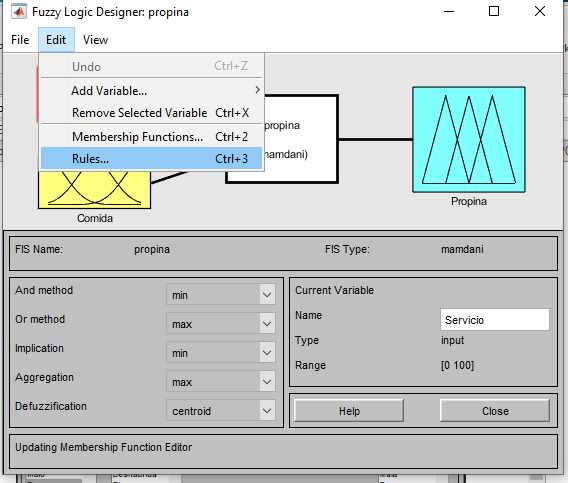

aqui se agregaran cada una de las reglas que se necesiten para generar el sistema difuso, en este caso dependiendo de la calidad de la comida y/o servicio, la propina sera asignada

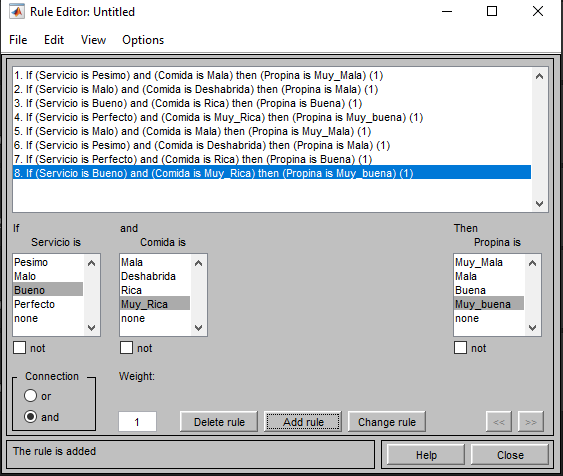

al ejecutar el archivo podemos observar el tipo de propina y los valores asignados y el funcionamiento de nuestro sistema, para eso vamos a la seccion View-Surface

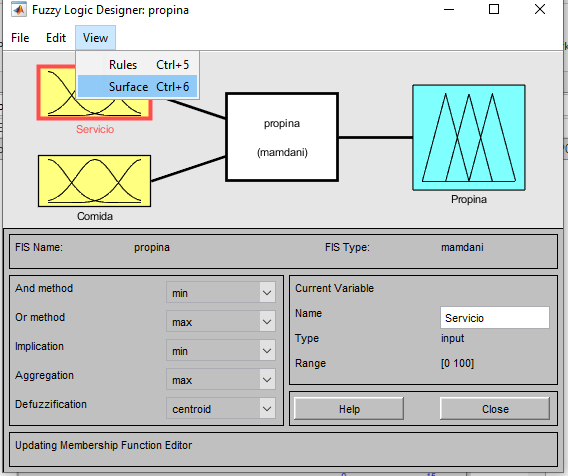

creara una ventana como la siguiente donde podremos observar el funcionamiento del sistema asi como editar los valores de servicio y comida para poder hacer un testeo de como se comportaria en dados casos.

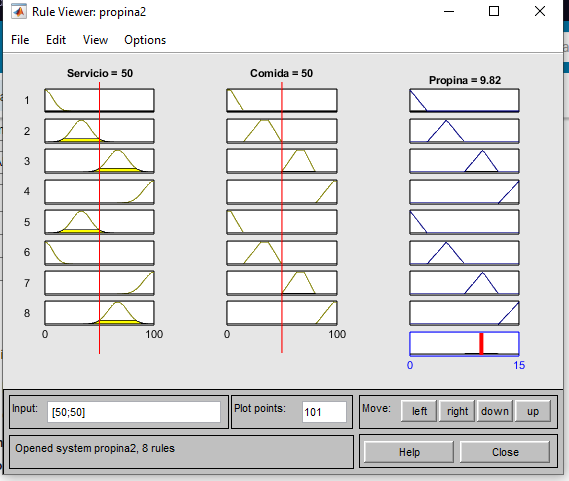

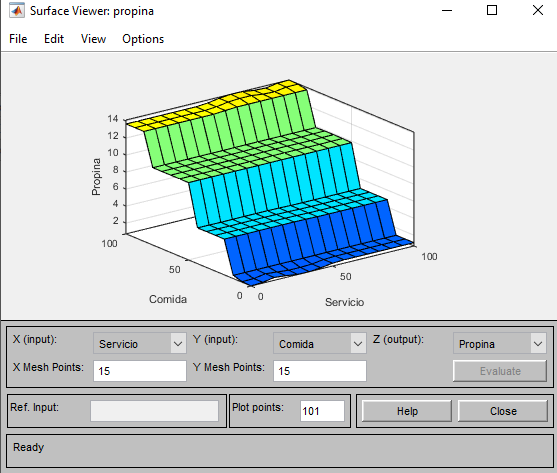

### ¿Existe una situación donde el problema usual tenga "mal desempeño" al compararlo con tu implementación?

al momento donde la propina es mala y la comida decente, ya que da valores variados entre propina decente y mala.

¿Existe una situación donde el problema usual tenga "mejor desempeño" al compararlo con tu implementación?

al ser la comida buena y el servicio bueno, tambien cuando la comida es mala y el servicio pesimo, la propina asignada da valores correctos.

# Problema 2

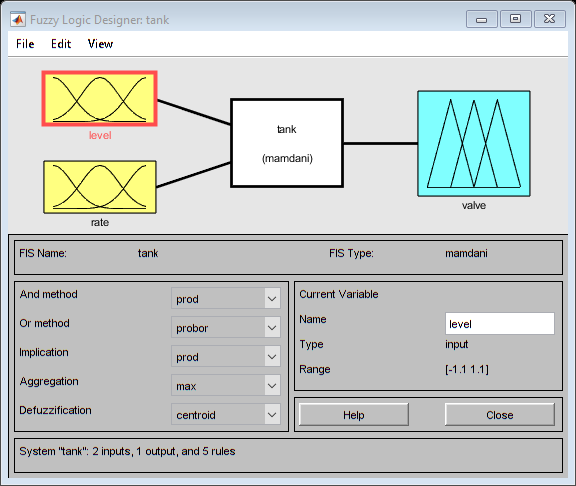

clc
clear all
close all

open_system('sltank')
fuzzyLogicDesigner(tank)

tank

tank =   mamfis with properties:

                       Name: "tank"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×5 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


### 2.2 ¿Cuantas variables linguisticas tiene?

2, level y rate

### **2.2** ¿Cuál es el universo de discurso de cada una?

Level [-1.1 1.1]

Rate [-0.35 0.35]

### **2.3** Grafica las conjuntos difusos de cada variable lingüistica

subplot(2,1,1)
plotmf(tank,'input',1)

subplot(2,1,2)
plotmf(tank,'input',2)

### **2.4** Muestra las reglas de inferencia difusa utilizadas

tank.rules

ans =   1×5 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                              Description                      
         ______________________________________________________

    1    "level==okay => valve=no_change (1)"                  
    2    "level==low => valve=open_fast (1)"                   
    3    "level==high => valve=close_fast (1)"                 
    4    "level==okay & rate==positive => valve=close_slow (1)"
    5    "level==okay & rate==negative => valve=open_slow (1)" 


### **2.5** Explica en que consiste la implementación del sistema (una descripción general de todos bloques) en especial los bloque de visualización, así como la simulación mostrada 

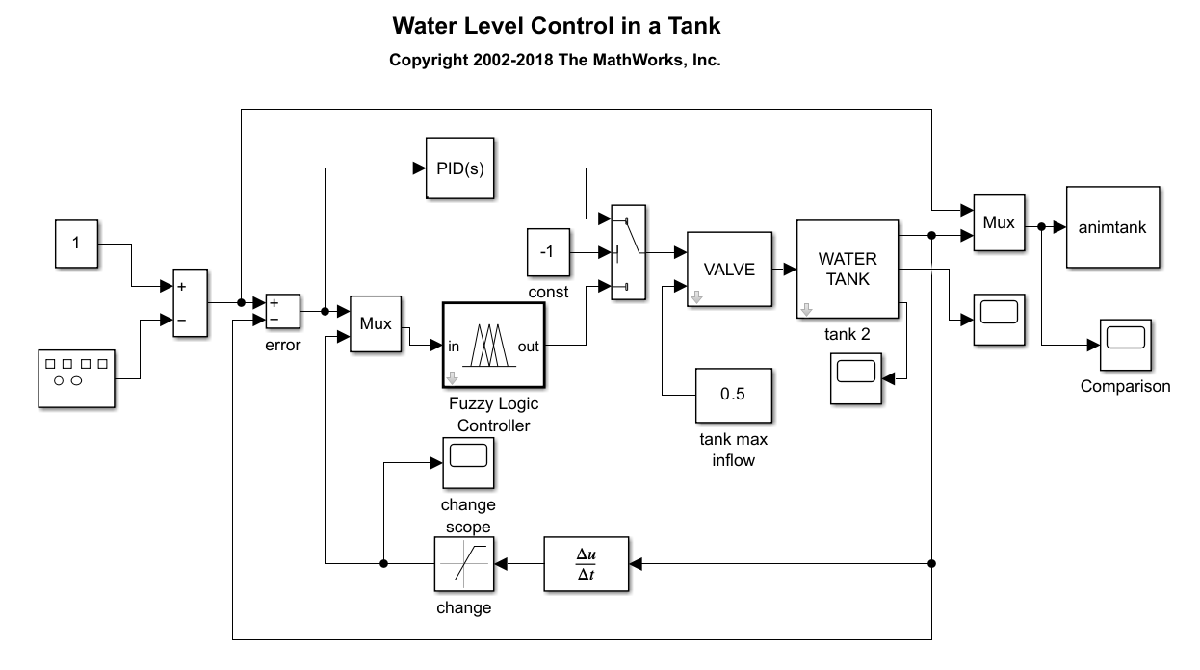

Los primeros tres bloques representan una simulación de carga y descarga de un tanque de agua. 

El bloque con el nombre de "error" representa la diferencia que existe entre la referencia y la salida del sistema, a esto se le conoce como error.

La salida del error va al controlador PID, el cual se encargará de corregir dicho error, y va para un elemento MUX, el cual permite unir 2 señales en 1 sin sumarlas. 

El bloque de Fuzzy Logic es el subsistema encargado de realizar las operaciones de la lógica difusa. De este cuadro sale a un switch encargado de controlar la valcula de agua dependiendo la situación en la que se encuentre el sistema, según las reglas de inferencia. 

La valvula se conecta al tanque de agua y lo llena. Este último bloque se une a un MUX junto con la referencia principal y se unen al bloque de animación, el cuál es el encargado de simular el llenado y vaciado del tanque de agua.

Del tanque de agua sale una señal hacía un bloque de derivación, el cuál representa la velocidad en la que el tanque se vacía o se llena, y este se une de nuevo al bloque de Fuzzy Logic, sirviendo como referencia de la nueva situación del tanque.

## Problema 3

La logica difusa se puede implementar en varias aplicaciones en ingeniería, tal es el caso de:

**Hela Lassoued, Raouf Ketata**, *Chapter 5 - Genetic fuzzy logic based system for arrhythmia classification*, Editor(s): Olfa Boubaker, Control Theory in Biomedical Engineering, Academic Press, 2020, Pages 105-127, ISBN 9780128213506. [Enlace](https://www.sciencedirect.com/science/article/pii/B9780128213506000056)

Contesta las siguentes preguntas respecto a la revisión del documento

**3.1** ¿Qué factores explican la presencia de arritmias?

R: El libro menciona que la mala salud, malos hábitos alimentarios, falta de actividad física, estrés elevado, antecedentes familiares y edad (entre muchos otros).

**3.2** ¿A qué se refieren las siglas DSS?

R: Son las siglas de "decision support system" (sistema de soporte de desiciones)

**3.3** ¿A qué se refieren las siglas FLC?

R: Son las siglas de "fuzzy logic controllers" (Controladores logicos difusos)

**3.4** ¿A qué se refieren las siglas GA?

R: En ingles "genetic algorithms" (algoritmos geneticos)

**3.5** ¿Cuál es el principal objetivo del capítulo 5?

R: Este capítulo describe la propuesta metodología de clasificación de arritmias, detalla los experimentos. y resultados, y la sección final proporciona una conclusión.

**3.6**  La base de datos  *MIT-BIH Arrhythmia Database* contine varios registros de distintos tipos de arritmias, ¿Cuáles son estos?   

R: 

- Ritmo del seno normal (NSR por sus siglas en ingles)

- Contracción Ventricular Prematura (PVC), 

- Izquierda Bloque de rama del haz (LBBB), 

- Bloque de rama del haz derecho (RBBB)

- Latidos con ritmo (P)

**3.7** ¿De que depende el desempeño de un  FLC?

R: De los parámetros de membresía y número de reglas ajustados por un GA

**3.8** ¿Para que utilizan un GA?

R: Se utiliza para activar la optimización de los parámetros de membresía  del error entre la salida prevista y su objetivo correspondiente.

**3.9** La Figura 1 muestra un diagrama de bloques de la metodología implementada para la clasificación de arritmias. En nuestro caso nos interesa el bloque de clasificación. Este está compuesto por configuración y optimización. ¿En que consisten las entradas (input features) que recibe este bloque de clasificación? 

R: Un pre-porcesamiento de las señal para filtrarla de los artefactos y extraer las características.

**3.10** La principal ventaja de un FLC es que no es necesario un modelo matemático para la implementación del controlador (difuso). En general esto es el caso (como en el ejemplo del Problema 2), aunque puede suceder que para resolver cierta clase de problemas  sea necesario el modelo matemático de un subsistema. Se espera que la Figura 10 sea transparente en este momento. De acuerdo al texto ¿Cuál es la diferencia entre la inferencia de Mamdani y Sugeno?

R:Que mientras para Mamdani el antecedente y la consecuencia son variables difusas,  para la inferencia de Sugeno, el antecedente es una variable difusa, pero la consecuencia es una función constante o lineal.

**3.11** De la sección 2.2.1 FLC configuration, ¿Cuántas variables lingüisticas se tienen? R: 3 MIN, MOY, MAX

¿Que tipo de conjuntos difusos son los consecuentes?

R:singletones

 ¿Cuantas reglas si-entones se proponen? 

R:5 (los tipos de arritmia)

¿Que sistemas de inferencia se utiliza?  

R:Mandami

 ¿Qué operaciones se utilizan para la Conjunción, Disyunción e Implicación?

R:Producto, suma y producto.

**3.12** Reporte el diagram de flujo del GA utilizado.

R:

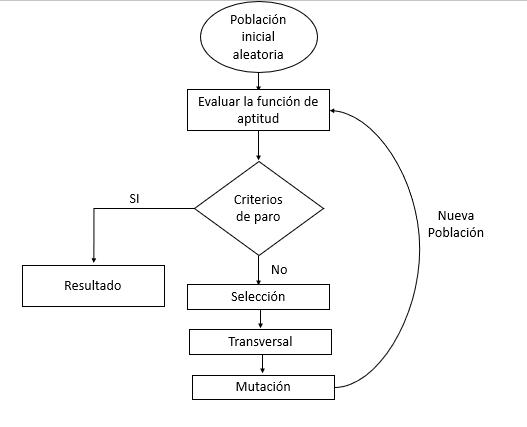

**3.13** Escriba la expresión matemática para la  *fitness function*  utilizada

R:


$$\textrm{RMSE}=\sqrt{\frac{!}{N}\sum_{I=0}^N {\left(t_i -o_i \right)}^2 }$$


**3.14** No se pretende profundizar sobre el funcionamiento del GA. Basta con tener una visión general de su uso en esta implementación, En particular los parametros a optimizar se les da el nombre de *cromosomas. *En este caso ¿Qué representan los cromosomas? 

R: El cromosoma representa los parámetros gaussianos (μ y δ) y el número de reglas difusas.

¿Cuáles son los resultados del proceso de optimización?

R:una tasa de cobertura entre los conjuntos difusos de entrada comparados a su universo discursivo. 

**3.15** ¿Cuáles fueron los resultados de la implementación?

R:Dos arritmias P y PVC no estan siendo clasificadas eficientemente.